# **TU: Time-Synchronous Average of Sinusoid**

Industrial AI & Automation by Y.K.Kim

Mod: 2024-2

## Introduction

Compute the time-synchronous average of a noisy sinusoid.

## Dataset

### Generate Signals

Generate a signal consisting of a sinusoid embedded in white Gaussian noise. The signal is sampled at 500 Hz for 20 seconds. Specify a sinusoid frequency of 10 Hz and a noise variance of 0.01. Plot one period of the signal.

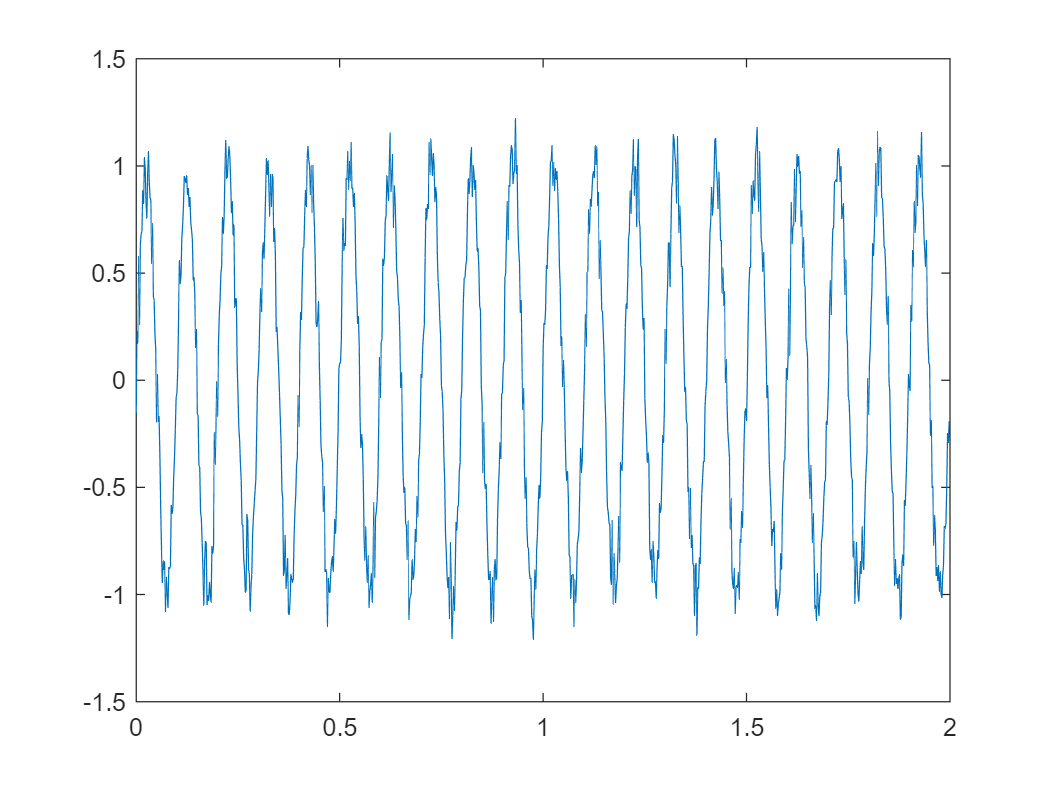

fs = 500;
t = 0:1/fs:2-1/fs;

f0 = 10;
y = sin(2*pi*f0*t) + randn(size(t))/10;

% Plot for All timeline
figure
plot(t,y)

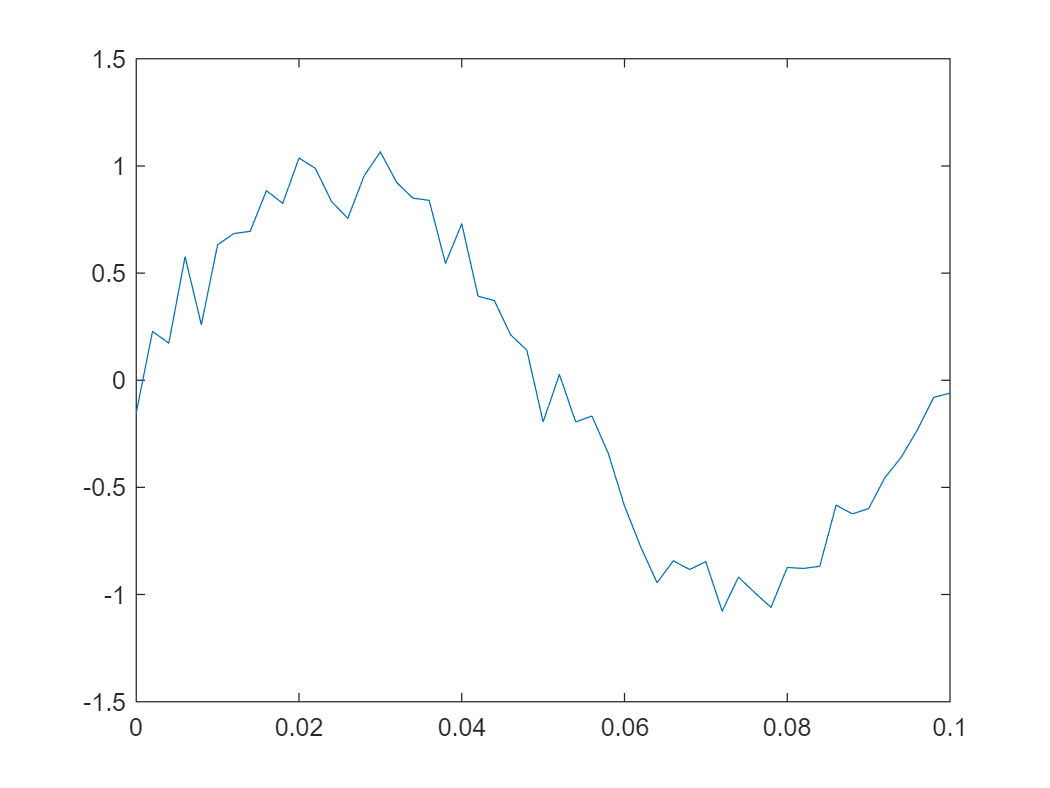


% Plot One Period
figure
plot(t,y)
xlim([0 1/f0])

## Example : TSA

Compute the time-synchronous average of the signal. For the synchronizing signal, use a set of pulses with the same period as the sinusoid. Use `tsa` without output arguments to display the result.

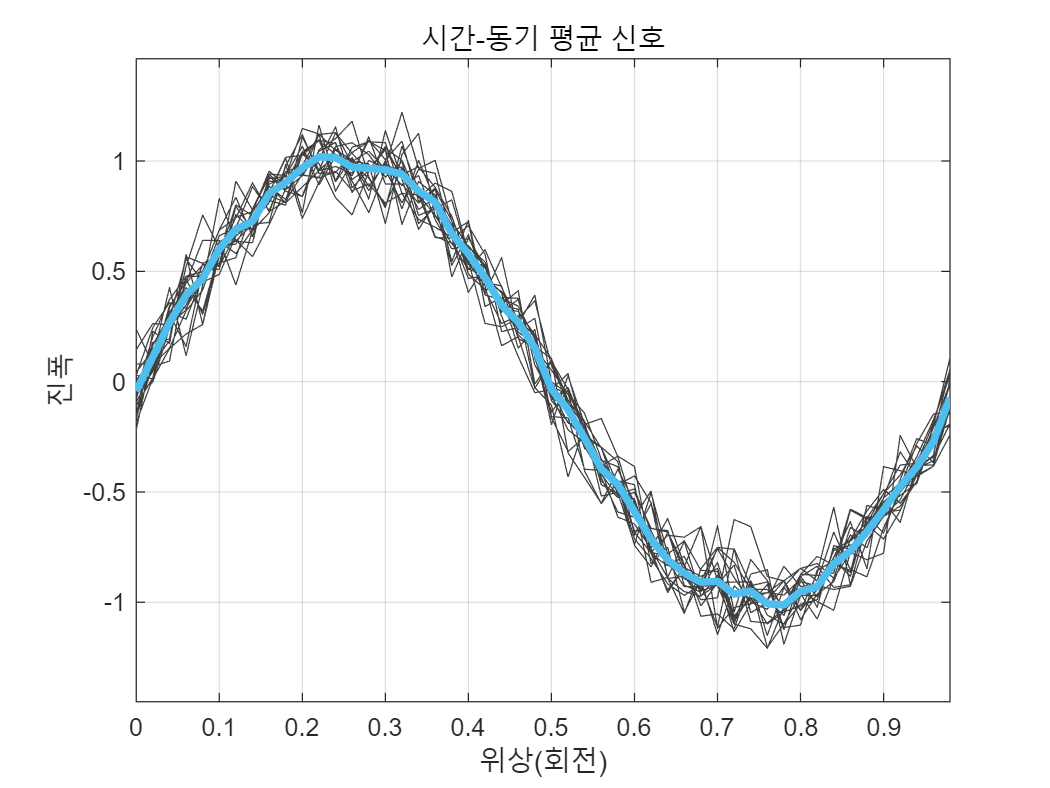

% Generate pulses
tPulse = 0:1/f0:max(t);   % 20 numbers

tsa(y,fs,tPulse)

# **Fan Switchoff**

Compute the time-synchronous average of the position of a fan blade as it slows down after switchoff.

A desk fan spinning at 2400 rpm is turned off. 

Fan rotor to stop in approximately 5 seconds. A high-speed camera measures the *x*-coordinate of one of the fan blades at a rate of 1 kHz.

fs = 1000;
t = 0:1/fs:5-1/fs;

rpm0 = 2400;

## Signal Generation

Idealize the fan blade as a point mass circling the rotor center at a radius of 10 cm. The blade experiences a drag force proportional to speed, resulting in the following expression for the phase angle:


$$\phi =2\pi f_0 T\left(1-e^{-t/T} \right),$$


where $f_0$ is the initial frequency and $T=0\ldotp 75$ second is the decay time.

a = 0.1;
f0 = rpm0/60;
T = 0.75;

phi = 2*pi*f0*T*(1-exp(-t/T));

Compute and plot the *x-* and *y*-coordinates. Add white Gaussian noise.

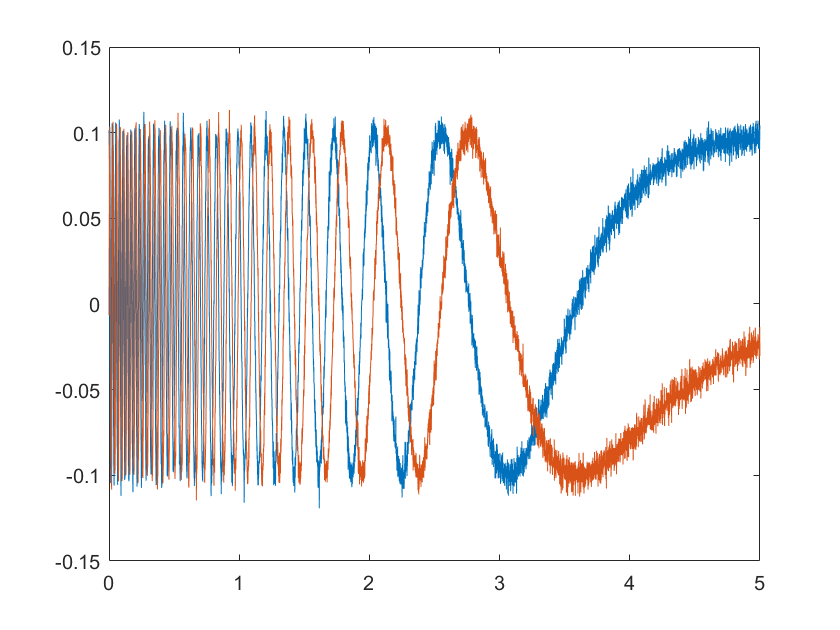

x = a*cos(phi) + randn(size(phi))/200;
y = a*sin(phi) + randn(size(phi))/200;

plot(t,x,t,y)

## Exercise : Find Pulse Times

Determine the synchronizing signal. Use the `tachorpm` function to find the pulse times. 

Limit the search to times before 2.5 seconds. 

Plot the rotational speed to see its exponential decay.

> also, can use  [`rpmtrack`](https://kr.mathworks.com/help/signal/ref/rpmtrack.html) 

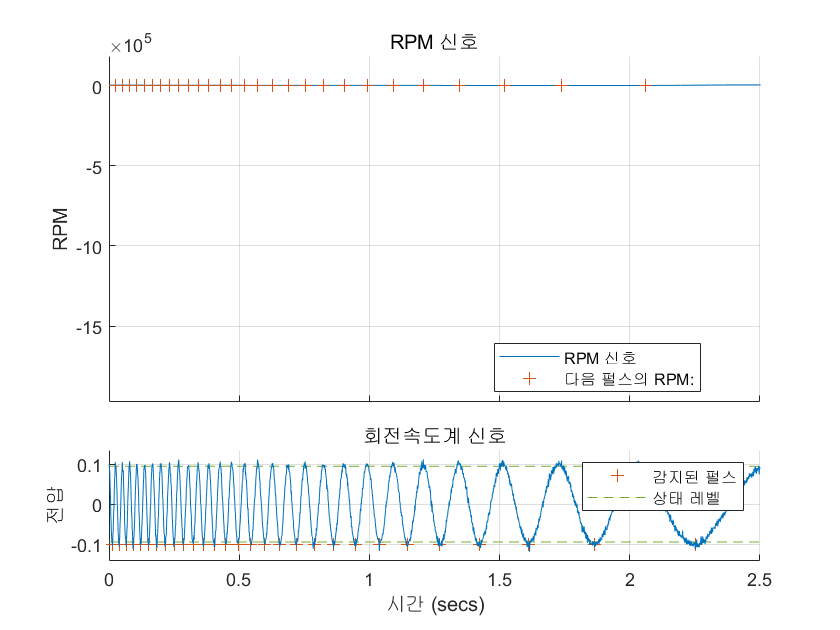

%%% YOUR CODE GOES HERE
%%% Find Tachometer Pulse (TP)
[rpm,~,tp] = tachorpm(x,fs,"PulsesPerRev",1);

% Plot for t<2.5
tachorpm(x,fs); xlim([0 2.5]); legend('Location','best');

Compute and plot the time-synchronous average signal, which corresponds to a period of a sinusoid. Perform the averaging in the frequency domain.

- Converts to FFT, Average Spectra , Then back to Time-domain

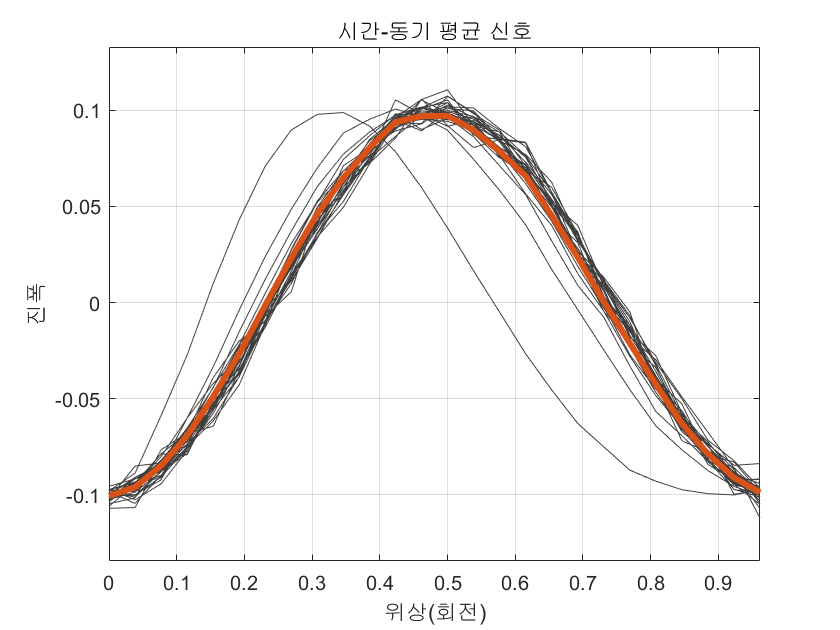

clf
%%% YOUR CODE GOES HERE
% TSA(________,'Method','fft')
tsa(x,fs, tp, 'Method','fft');

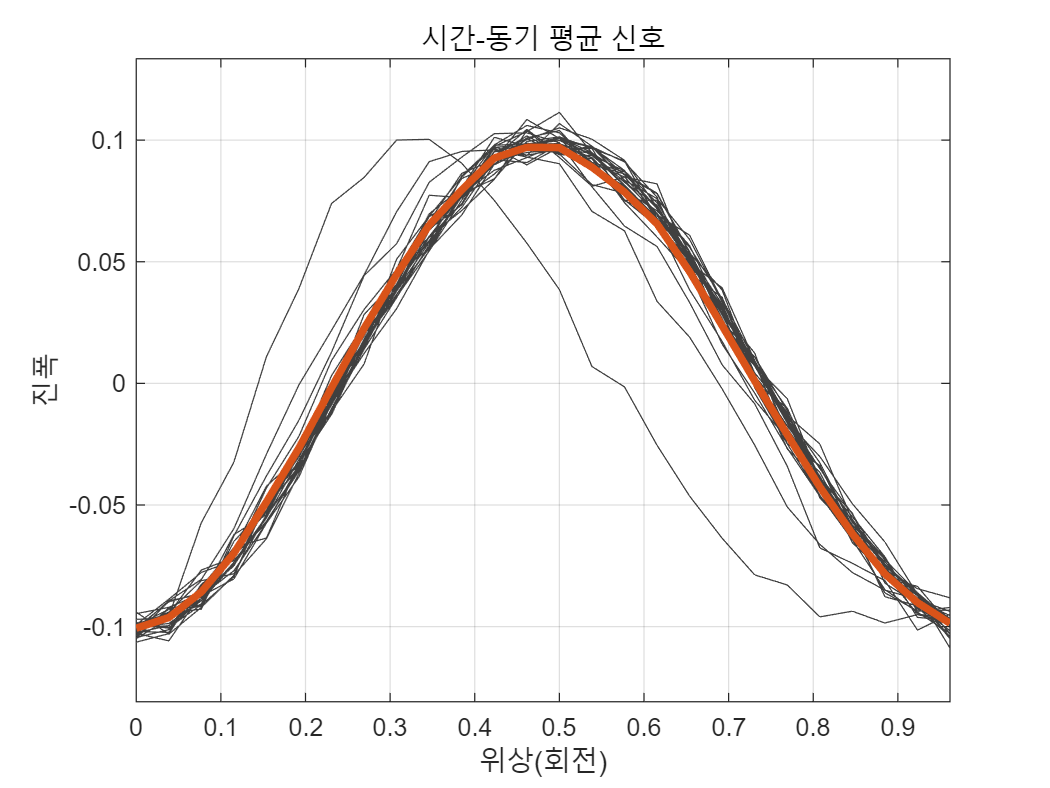

tsa(x,fs, tp);